# Train and Deploy Fully Convolutional Networks for Semantic Segmentation

This example shows how to train and deploy a fully convolutional semantic segmentation network on an NVIDIA® GPU by using GPU Coder™.

A semantic segmentation network classifies every pixel in an image, resulting in an image that is segmented by class. Applications for semantic segmentation include road segmentation for autonomous driving and cancer cell segmentation for medical diagnosis. To learn more, see [Semantic Segmentation Basics](docid:vision_ug.mw_1d343c03-9e01-4466-be83-06053df3f8a0).

To illustrate the training procedure, this example trains FCN-8s [1], one type of convolutional neural network (CNN) designed for semantic image segmentation. Other types of networks for semantic segmentation include fully convolutional networks, such as SegNet and U-Net. You can apply this training procedure to those networks too.

This example uses the [CamVid dataset](http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/) [2] from the University of Cambridge for training. This data set is a collection of images containing street-level views obtained while driving. The data set provides pixel-level labels for 32 semantic classes including car, pedestrian, and road.

## Third-party Prerequisites

### Required

- CUDA® enabled NVIDIA GPU and compatible driver.

### Optional

- NVIDIA CUDA toolkit.

- NVIDIA cuDNN library.

- Environment variables for the compilers and libraries. For information on the supported versions of the compilers and libraries, see  [Third-party Products](docid:gpucoder_gs#mw_aa8b0a39-45ea-4295-b244-52d6e6907bff). For setting up the environment variables, see  [Environment Variables](docid:gpucoder_gs#mw_453fbbd7-fd08-44a8-9113-a132ed383275).

## Verify GPU Environment

Use the [coder.checkGpuInstall](docid:gpucoder_ref#mw_0957d820-192f-400a-8045-0bb746a75278) function to verify that the compilers and libraries necessary for running this example are set up correctly.

envCfg = coder.gpuEnvConfig('host');
envCfg.DeepLibTarget = 'cudnn';
envCfg.DeepCodegen = 1;
envCfg.Quiet = 1;
coder.checkGpuInstall(envCfg);

## Setup

This example creates the fully convolutional semantic segmentation network with weights initialized from the VGG-16 network. The vgg16 function checks for the existence of the Deep Learning Toolbox Model for VGG-16 Network support package and returns a pretrained VGG-16 model.

vgg16();

Download a pretrained version of FCN. This pretrained model enables you to run the entire example without waiting for the training to complete. The doTraining flag controls whether the example uses the trained network of the example or the pretrained FCN network for code generation.

doTraining = false;
if ~doTraining
    pretrainedURL = 'https://www.mathworks.com/supportfiles/gpucoder/cnn_models/fcn/FCN8sCamVid.mat';
    disp('Downloading pretrained FCN (448 MB)...');
    websave('FCN8sCamVid.mat',pretrainedURL);
end

## Download CamVid Dataset

Download the CamVid dataset from these URLs.

imageURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/files/701_StillsRaw_full.zip';
labelURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/data/LabeledApproved_full.zip';

outputFolder = fullfile(pwd,'CamVid');

if ~exist(outputFolder, 'dir')
   
    mkdir(outputFolder)
    labelsZip = fullfile(outputFolder,'labels.zip');
    imagesZip = fullfile(outputFolder,'images.zip');   
    
    disp('Downloading 16 MB CamVid dataset labels...'); 
    websave(labelsZip, labelURL);
    unzip(labelsZip, fullfile(outputFolder,'labels'));
    
    disp('Downloading 557 MB CamVid dataset images...');  
    websave(imagesZip, imageURL);       
    unzip(imagesZip, fullfile(outputFolder,'images'));    
end

The data download time depends on your Internet connection. The example execution does not proceed until the download operation is complete. Alternatively, use your web browser to first download the data set to your local disk. Then, use the outputFolder variable to point to the location of the downloaded file.

## Load CamVid Images

Use [imageDatastore](docid:matlab_ref.butueui-1) to load CamVid images. The imageDatastore enables you to efficiently load a large collection of images onto a disk.

imgDir = fullfile(outputFolder,'images','701_StillsRaw_full');
imds = imageDatastore(imgDir);

Display one of the images.

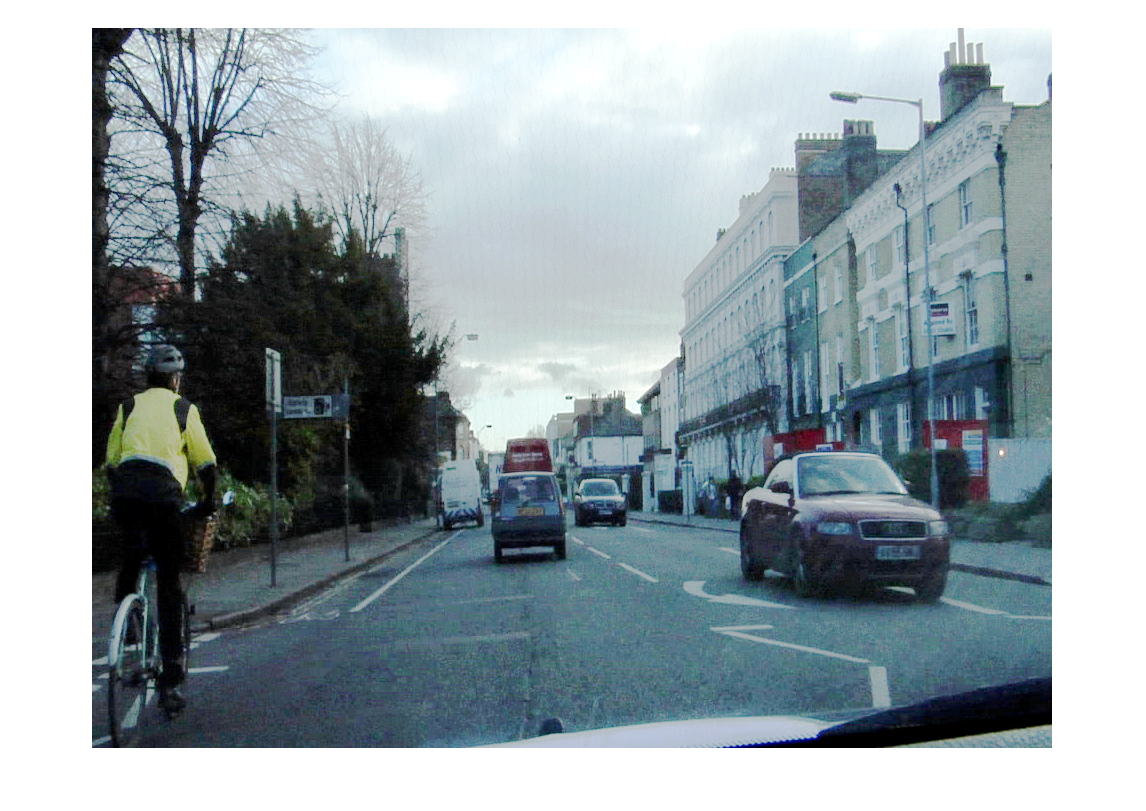

I = readimage(imds,25);
I = histeq(I);
imshow(I)

## Load CamVid Pixel-Labeled Images

Use [pixelLabelDatastore](docid:vision_ref.mw_c2246553-ba4a-4bad-aad4-6ab8fa2f7f2d) to load CamVid pixel label image data. A pixelLabelDatastore encapsulates the pixel label data and the label ID to a class name mapping.

Following the training method described in the SegNet paper [3], group the 32 original classes in CamVid to 11 classes. Specify these classes.

classes = [
    "Sky"
    "Building"
    "Pole"
    "Road"
    "Pavement"
    "Tree"
    "SignSymbol"
    "Fence"
    "Car"
    "Pedestrian"
    "Bicyclist"
    ];

To reduce 32 classes into 11 classes, multiple classes from the original data set are grouped together. For example, "Car" is a combination of "Car", "SUVPickupTruck", "Truck_Bus", "Train", and "OtherMoving". Return the grouped label IDs by using the `camvidPixelLabelIDs` supporting function.

labelIDs = camvidPixelLabelIDs();

Use the classes and label IDs to create the pixelLabelDatastore.

labelDir = fullfile(outputFolder,'labels');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

Read and display one of the pixel-labeled images by overlaying it on top of an image.

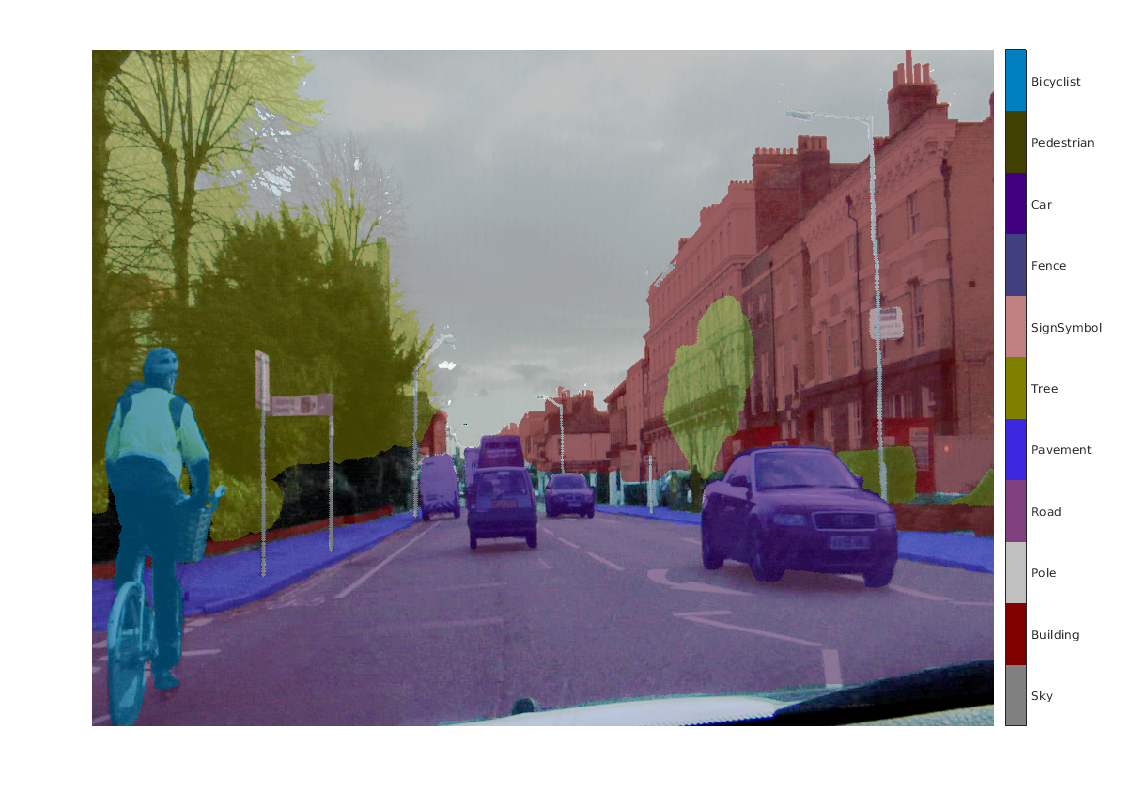

C = readimage(pxds,25);
cmap = camvidColorMap;
B = labeloverlay(I,C,'ColorMap',cmap);
imshow(B)
pixelLabelColorbar(cmap,classes);

Areas with no color overlay do not have pixel labels and are not used during training.

## Analyze Data Set Statistics

To see the distribution of class labels in the CamVid dataset, use [countEachLabel](docid:vision_ref.mw_1c600e69-1a15-4538-9629-7bceaafbd4e7). This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 11×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________

    {'Sky'       }    7.6801e+07      4.8315e+08   
    {'Building'  }    1.1737e+08      4.8315e+08   
    {'Pole'      }    4.7987e+06      4.8315e+08   
    {'Road'      }    1.4054e+08      4.8453e+08   
    {'Pavement'  }    3.3614e+07      4.7209e+08   
    {'Tree'      }    5.4259e+07       4.479e+08   
    {'SignSymbol'}    5.2242e+06      4.6863e+08   
    {'Fence'     }    6.9211e+06       2.516e+08   
    {'Car'       }    2.4437e+07      4.8315e+08   
    {'Pedestrian'}    3.4029e+06      4.4444e+08   
    {'Bicyclist' }    2.5912e+06      2.6196e+08   


Visualize the pixel counts by class.

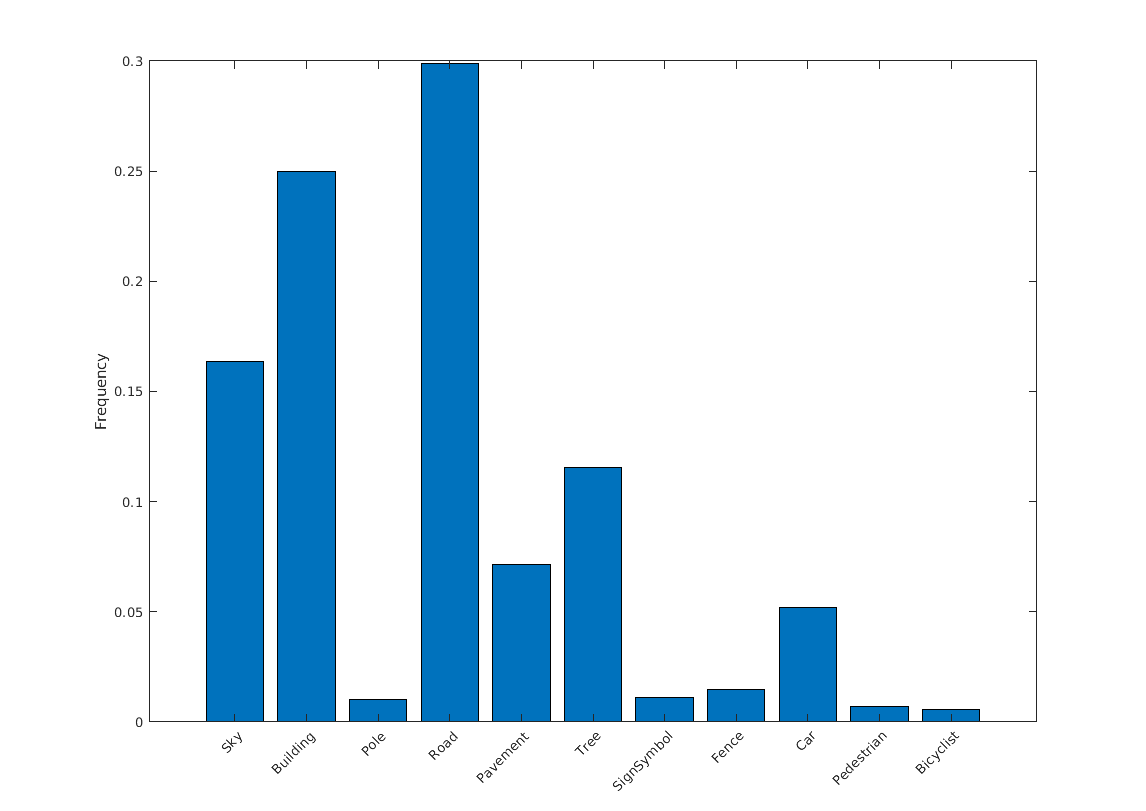

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

Ideally, all classes have an equal number of observations. The classes in CamVid are imbalanced, which is a common issue in automotive data sets of street scenes. Such scenes have more sky, building, and road pixels than pedestrian and bicyclist pixels because sky, buildings, and roads cover more area in the image. If not handled correctly, this imbalance can be detrimental to the learning process because the learning is biased in favor of the dominant classes. Later on in this example, you use class weighting to handle this issue.

## Resize CamVid Data

The images in the CamVid data set are 720-by-960. To reduce training time and memory usage, resize the images and pixel label images to 360-by-480 by using the `resizeCamVidImages` and `resizeCamVidPixelLabels`  supporting functions.

imageFolder = fullfile(outputFolder,'imagesResized',filesep);
imds = resizeCamVidImages(imds,imageFolder);

labelFolder = fullfile(outputFolder,'labelsResized',filesep);
pxds = resizeCamVidPixelLabels(pxds,labelFolder);

## Prepare Training and Test Sets

SegNet is trained by using 60% of the images from the dataset. The rest of the images are used for testing. The following code randomly splits the image and pixel label data into a training set and a test set.

[imdsTrain,imdsTest,pxdsTrain,pxdsTest] = partitionCamVidData(imds,pxds);

The 60/40 split results in the following number of training and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 421

numTestingImages = numel(imdsTest.Files)

numTestingImages = 280

## Create Network

Use [fcnLayers](docid:vision_ref#mw_163c29ab-59c2-4f7d-9d8c-65801e90c017) to create fully convolutional network layers initialized by using VGG-16 weights. The `fcnLayers` function performs the network transformations to transfer the weights from VGG-16 and adds the additional layers required for semantic segmentation. The output of the `fcnLayers` function is a LayerGraph object representing FCN. A  LayerGraph object encapsulates the network layers and the connections between the layers.

imageSize = [360 480];
numClasses = numel(classes);
lgraph = fcnLayers(imageSize,numClasses);

The image size is selected based on the size of the images in the dataset. The number of classes is selected based on the classes in CamVid.

## Balance Classes by Using Class Weighting

The classes in CamVid are not balanced. To improve training, you can use the pixel label counts computed earlier by the [countEachLabel](docid:vision_ref.mw_1c600e69-1a15-4538-9629-7bceaafbd4e7) function and calculate the median frequency class weights [3].

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq;

Specify the class weights by using a [pixelClassificationLayer](docid:vision_ref.mw_783aebd8-1ff1-4bc6-8508-90c8b71fca32).

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights)

pxLayer =   PixelClassificationLayer with properties:

            Name: 'labels'
         Classes: [11×1 categorical]
    ClassWeights: [11×1 double]
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


Update the SegNet network that has the new pixelClassificationLayer by removing the current pixelClassificationLayer and adding the new layer. The current  pixelClassificationLayer is named 'pixelLabels'. Remove it by using the [removeLayers](docid:nnet_ref.mw_a6f418c8-7e87-4f76-9ab8-da0230cceb11) function, add the new one by using the [addLayers](docid:nnet_ref.mw_25b609b6-6b6a-4ab9-9353-09f6efd0bf74) function, and connect the new layer to the rest of the network by using the [connectLayers](docid:nnet_ref.mw_245cd580-91e4-4ba0-8efd-73ef7987af1d) function.

lgraph = removeLayers(lgraph,'pixelLabels');
lgraph = addLayers(lgraph, pxLayer);
lgraph = connectLayers(lgraph,'softmax','labels');

## Select Training Options

The optimization algorithm for training is Adam, which is derived from *adaptive moment estimation*. Use the [trainingOptions](docid:nnet_ref.bu59f0q) function to specify the hyperparameters used for Adam.

options = trainingOptions('adam', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',100, ...  
    'MiniBatchSize',4, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', tempdir, ...
    'VerboseFrequency',2);

A 'MiniBatchSize' of four reduces memory usage while training. You can increase or decrease this value based on the amount of GPU memory in your system. 

 'CheckpointPath' is set to a temporary location. This name-value pair enables the saving of network checkpoints at the end of every training epoch. If training is interrupted due to a system failure or power outage, you can resume training from the saved checkpoint. Make sure that the location specified by 'CheckpointPath' has enough space to store the network checkpoints. 

## Data Augmentation

Data augmentation is used to improve network accuracy by randomly transforming the original data during training. By using data augmentation, you can add more variety to the training data without increasing the number of labeled training samples. To apply the same random transformation to both image and pixel label data use datastore combine and transform. First, combine `imdsTrain` and `pxdsTrain`.

dsTrain = combine(imdsTrain, pxdsTrain);

Next, use datastore transform to apply the desired data augmentation defined in the supporting function `augmentImageAndLabel`. Here, random left/right reflection and random X/Y translation of +/- 10 pixels is used for data augmentation.

xTrans = [-10 10];
yTrans = [-10 10];
dsTrain = transform(dsTrain, @(data)augmentImageAndLabel(data,xTrans,yTrans));

Note that data augmentation is not applied to the test and validation data. Ideally, test and validation data should be representative of the original data and is left unmodified for unbiased evaluation.

## Start Training

Start training using `trainNetwork` if the `doTraining` flag is true. Otherwise, load a pretrained network.

The training was verified on an NVIDIA™ Titan Xp with 12 GB of GPU memory. If your GPU has less memory, you might run out of memory. If you do not have enough memory in your system, try lowering the `MiniBatchSize` property in `trainingOptions` to 1. Training this network takes about 5 hours or longer depending on your GPU hardware. 

doTraining = false;
if doTraining    
    [net, info] = trainNetwork(dsTrain,lgraph,options);
    save('FCN8sCamVid.mat','net');
end

Save the DAG network object as a MAT-file named `FCN8sCamVid.mat`. This MAT-file is used during code generation.

## Perform MEX Code-generation

The `fcn_predict` function takes an image input and performs prediction on the image by using the deep learning network saved in `FCN8sCamVid.mat` file. The function loads the network object from `FCN8sCamVid.mat` into a persistent variable *mynet *and reuses the persistent object on subsequent prediction calls.

type('fcn_predict.m')

function out = fcn_predict(in)
%#codegen
% Copyright 2018-2019 The MathWorks, Inc.

persistent mynet;

if isempty(mynet)
    mynet = coder.loadDeepLearningNetwork('FCN8sCamVid.mat');
end

% pass in input
out = predict(mynet,in);


Generate a GPU Configuration object for MEX target setting target language to C++. Use the [coder.DeepLearningConfig](docid:gpucoder_ref#mw_e8e85f8e-8dde-45b6-9ec5-f121a79dc48f) function to create a c`uDNN` deep learning configuration object and assign it to the `DeepLearningConfig` property of the GPU code configuration object. Run the [codegen](docid:coder_ref#br46oyi-1) command specifying an input size [360, 480, 3]. This size corresponds to the input layer of FCN.

cfg = coder.gpuConfig('mex');
cfg.TargetLang = 'C++';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
codegen -config cfg fcn_predict -args {ones(360,480,3,'uint8')} -report

Code generation successful: View report


## Run Generated MEX

Load and display an input image.

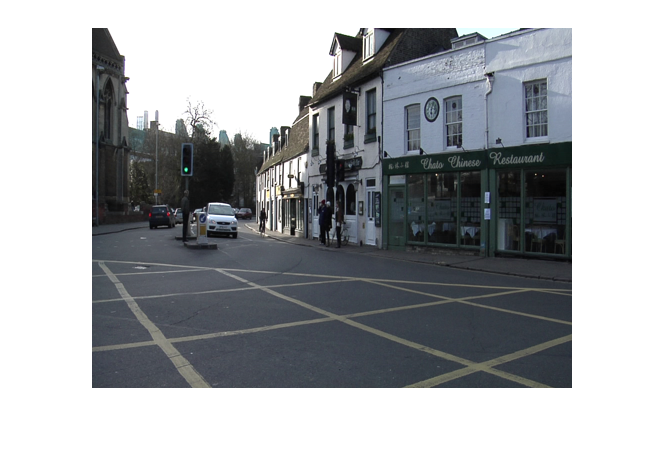

im = imread('testImage.png');
imshow(im);

Run prediction by calling `fcn_predict_mex` on the input image.

predict_scores = fcn_predict_mex(im);

The `predict_scores` variable is a three-dimensional matrix having 11 channels corresponding to the pixel-wise prediction scores for every class. Compute the channel by using the maximum prediction score to get pixel-wise labels.

[~,argmax] = max(predict_scores,[],3);

Overlay the segmented labels on the input image and display the segmented region.

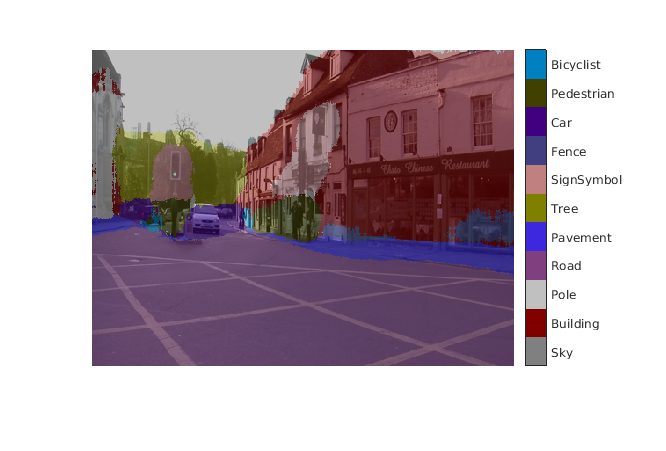

classes = [
    "Sky"
    "Building"
    "Pole"
    "Road"
    "Pavement"
    "Tree"
    "SignSymbol"
    "Fence"
    "Car"
    "Pedestrian"
    "Bicyclist"
    ];

cmap = camvidColorMap();
SegmentedImage = labeloverlay(im,argmax,'ColorMap',cmap);
figure
imshow(SegmentedImage);
pixelLabelColorbar(cmap,classes);

## Cleanup

Clear the static network object that was loaded in memory.

clear mex;

## Supporting Functions

function data = augmentImageAndLabel(data, xTrans, yTrans)
% Augment images and pixel label images using random reflection and
% translation.

for i = 1:size(data,1)
    
    tform = randomAffine2d(...
        'XReflection',true,...
        'XTranslation', xTrans, ...
        'YTranslation', yTrans);
    
    % Center the view at the center of image in the output space while
    % allowing translation to move the output image out of view.
    rout = affineOutputView(size(data{i,1}), tform, 'BoundsStyle', 'centerOutput');
    
    % Warp the image and pixel labels using the same transform.
    data{i,1} = imwarp(data{i,1}, tform, 'OutputView', rout);
    data{i,2} = imwarp(data{i,2}, tform, 'OutputView', rout);
    
end
end

## References

[1] Long, J., E. Shelhamer, and T. Darrell. "Fully Convolutional Networks for Semantic Segmentation." Proceedings of the IEEE Conference on Computer Vision and Pattern Recognition, 2015, pp. 3431–3440.

[2] Brostow, G. J., J. Fauqueur, and R. Cipolla. "Semantic object classes in video: A high-definition ground truth database." *Pattern Recognition Letters*. Vol. 30, Issue 2, 2009, pp 88-97.

[3] Badrinarayanan, V., A. Kendall, and R. Cipolla. "SegNet: A Deep Convolutional Encoder-Decoder Architecture for Image Segmentation." arXiv preprint arXiv:1511.00561, 2015.

*Copyright 2018-2021 The MathWorks, Inc.*